clf;
clear;

guitar = imread("../materials/guitar.tif");
size(guitar)

ans =    388   133


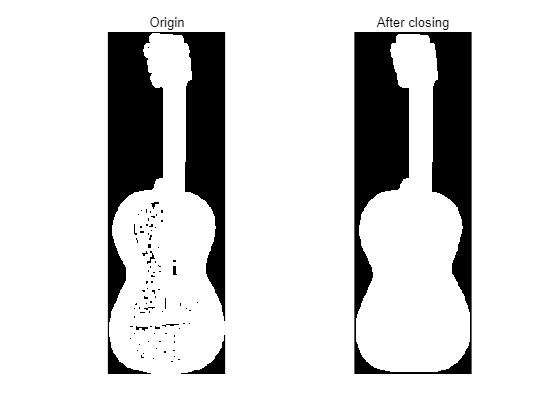


subplot(1,2,1);
imshow(guitar);title('Origin');

closing = my_closing(guitar);

subplot(1,2,2);
imshow(closing,[]);title('After closing');

function output = my_closing(image)
    [M,N] = size(image);
    %zero padding
    tmp = zeros(M+4,N+4);
    tmp(3:M+2,3:N+2) = image;

    %Dilation
    Dilation = zeros(M+4,N+4);
    for r = 3:M+2
        for c = 3:N+2
            or0 = bitor(tmp(r-2, c-2), bitor(bitor(tmp(r-2,c-1),tmp(r-2,c)), bitor(tmp(r-2,c+1),tmp(r-2,c+2))));
            or1 = bitor(tmp(r-1, c-2), bitor(bitor(tmp(r-1,c-1),tmp(r-1,c)), bitor(tmp(r-1,c+1),tmp(r-1,c+2))));
            or2 = bitor(tmp(r, c-2), bitor(bitor(tmp(r,c-1),tmp(r,c)), bitor(tmp(r,c+1),tmp(r,c+2))));
            or3 = bitor(tmp(r+1, c-2), bitor(bitor(tmp(r+1,c-1),tmp(r+1,c)), bitor(tmp(r+1,c+1),tmp(r+1,c+2))));
            or4 = bitor(tmp(r+2, c-2), bitor(bitor(tmp(r+2,c-1),tmp(r+2,c)), bitor(tmp(r+2,c+1),tmp(r+2,c+2))));
            Dilation(r, c) = bitor(or0, bitor(bitor(or1, or2), bitor(or3,or4)));
        end
    end
    
    %Erosion
    Erosion = zeros(M+4,N+4);
    for r = 3:M+2
        for c = 3:N+2
            and0 = bitand(Dilation(r-2, c-2), bitand(bitand(Dilation(r-2, c), Dilation(r-2, c)), bitand(Dilation(r-2, c+1), Dilation(r-2, c+2))));
            and1 = bitand(Dilation(r-1, c-2), bitand(bitand(Dilation(r-1, c), Dilation(r-1, c)), bitand(Dilation(r-1, c+1), Dilation(r-1, c+2))));
            and2 = bitand(Dilation(r, c-2), bitand(bitand(Dilation(r, c), Dilation(r, c)), bitand(Dilation(r, c+1), Dilation(r, c+2))));
            and3 = bitand(Dilation(r+1, c-2), bitand(bitand(Dilation(r+1, c), Dilation(r+1, c)), bitand(Dilation(r+1, c+1), Dilation(r+1, c+2))));
            and4 = bitand(Dilation(r+2, c-2), bitand(bitand(Dilation(r+2, c), Dilation(r+2, c)), bitand(Dilation(r+2, c+1), Dilation(r+2, c+2))));
            Erosion(r, c) = bitand(and0, bitand(bitand(and1, and2), bitand(and3, and4)));
        end
    end

    output = Erosion(3:M+2,3:N+2);
end